## Sound analysis lecture

clear
[signal,Fs] = audioread('AudioTest\DJ_TAYE_midi_DJ_TAYE_midi_crown_chakra_120_F#m.wav');


signal = signal(:,1) % signal = toutes les lignes de la première colonne

signal =    -0.0002
   -0.0004
   -0.0005
   -0.0006
   -0.0007
   -0.0007
   -0.0008
   -0.0008
   -0.0009
   -0.0009


FFTSize = 4096;
hopsize = 200; %changer de nom overlapp, overlap = nombre de samples commun
overlapp = FFTSize -hopsize;

[FFTVector,frequencyBand,newTime] = spectrogram (signal,FFTSize,overlapp,FFTSize-1,Fs,'yaxis')

FFTVector = 	1.0e+02 *

  -0.0078 + 0.0000i  -0.0078 + 0.0000i  -0.0071 + 0.0000i  -0.0062 + 0.0000i  -0.0052 + 0.0000i  -0.0044 + 0.0000i  -0.0036 + 0.0000i  -0.0027 + 0.0000i  -0.0019 + 0.0000i  -0.0015 + 0.0000i  -0.0016 + 0.0000i  -0.0010 + 0.0000i  -0.0002 + 0.0000i   0.0002 + 0.0000i  -0.0009 + 0.0000i  -0.0009 + 0.0000i   0.0005 + 0.0000i   0.0018 + 0.0000i   0.0014 + 0.0000i   0.0016 + 0.0000i   0.0015 + 0.0000i   0.0033 + 0.0000i   0.0027 + 0.0000i   0.0021 + 0.0000i   0.0025 + 0.0000i   0.0034 + 0.0000i   0.0033 + 0.0000i   0.0023 + 0.0000i   0.0020 + 0.0000i   0.0027 + 0.0000i   0.0028 + 0.0000i   0.0011 + 0.0000i   0.0005 + 0.0000i   0.0017 + 0.0000i   0.0019 + 0.0000i  -0.0008 + 0.0000i  -0.0010 + 0.0000i   0.0005 + 0.0000i   0.0007 + 0.0000i  -0.0001 + 0.0000i  -0.0011 + 0.0000i  -0.0006 + 0.0000i   0.0005 + 0.0000i  -0.0006 + 0.0000i  -0.0017 + 0.0000i  -0.0017 + 0.0000i  -0.0004 + 0.0000i  -0.0007 + 0.0000i  -0.0023 + 0.0000i  -0.0026 + 0.0000i
   0.0029 + 0.0000i   0.0

frequencyBand = 	1.0e+04 *

         0
    0.0012
    0.0023
    0.0035
    0.0047
    0.0059
    0.0070
    0.0082
    0.0094
    0.0105


newTime =     0.0427    0.0468    0.0510    0.0552    0.0593    0.0635    0.0677    0.0718    0.0760    0.0802    0.0843    0.0885    0.0927    0.0968    0.1010    0.1052    0.1093    0.1135    0.1177    0.1218    0.1260    0.1302    0.1343    0.1385    0.1427    0.1468    0.1510    0.1552    0.1593    0.1635    0.1677    0.1718    0.1760    0.1802    0.1843    0.1885    0.1927    0.1968    0.2010    0.2052    0.2093    0.2135    0.2177    0.2218    0.2260    0.2302    0.2343    0.2385    0.2427    0.2468


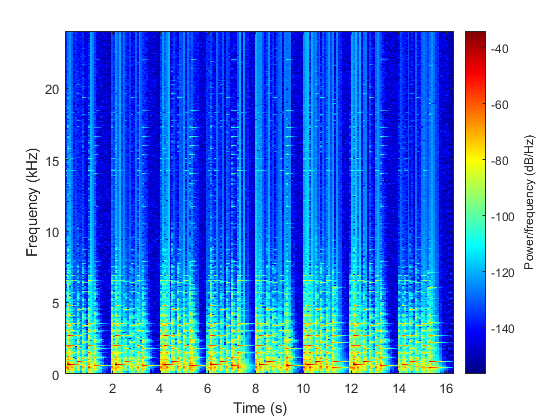

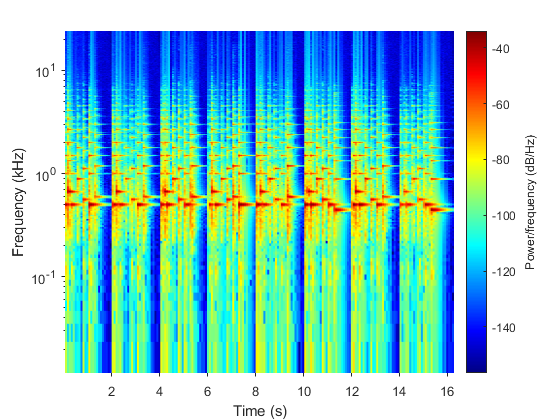

spectrogram (signal,FFTSize,hopsize,FFTSize,Fs,'yaxis');
colormap jet
set(gca, 'YScale', 'log')

N = length(signal)

N = 786250

time = [0:N-1]/Fs

time =          0    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010


%le nombre de FFT a effectuer pour couvrir tout le signal
numberFFT  = size(FFTVector,2)

numberFFT = 3911



unwrappedPhase = zeros(FFTSize/2,numberFFT)

unwrappedPhase =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

deltaPhi = zeros(FFTSize/2,numberFFT)

deltaPhi =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

%enveloppe folower
EnveloppeFolow = zeros(numberFFT)

EnveloppeFolow =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0  

%local energieFolower
LocalEnergieFolow = zeros(numberFFT,1)

LocalEnergieFolow =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%vector pour garder l'énergie de la FFT - version sans pondération
%fréquentielle
FFT_SimpleEnergie = zeros(numberFFT,1)

FFT_SimpleEnergie =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%vector pour garder l'énergie de la FFT - version sans pondération
%fréquentielle
FFT_HFC = zeros(numberFFT,1)

FFT_HFC =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



%vector pour enregistrer les différences de spectres entre deux FFT
FFT_spectralDiff = zeros(numberFFT,1)

FFT_spectralDiff =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



sumDeltaPhi = zeros(numberFFT,1)

sumDeltaPhi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


%new time est la nouvelle Fs, on sample moins vite, on divise Fs par
%l'overlapp




%indexFFT parcours le nombre de FFT a effectuer de 0 à numberFFT-1
%indexPosition parcours la FFT de 1 à la taille de la FFT

for indexFFT = 0:1:numberFFT-1 

    %the value contient la portion de signal a traiter
    %TODO : fonction fenetrage
    theValue = signal(1+indexFFT*hopsize:FFTSize+indexFFT*hopsize);
    
    
    unwrappedPhase(:,indexFFT+1) = angle(FFTVector(:,indexFFT+1));
    
    EnveloppeFolow(indexFFT+1) = 1/FFTSize * sum(abs(theValue));
    LocalEnergieFolow(indexFFT+1) = 1/FFTSize *sum(theValue.^2);
    %la boucle parcours tous les élèments de la FFT
    for indexPosition = 1:1:FFTSize/2         
        %pour chaque FFT, on calcule son énergie et on la met dans un tableau
        FFT_SimpleEnergie(indexFFT+1) = FFT_SimpleEnergie(indexFFT+1,1) + (abs(FFTVector(indexPosition,indexFFT+1)))^2;
        
        FFT_HFC(indexFFT+1,1) = FFT_HFC(indexFFT+1,1) + indexPosition*(abs(FFTVector(indexPosition,indexFFT+1)))^2;
        
        % si on a deja effectuer une FFT
        if(indexFFT > 0)
            %algorithme spectral difference
            
            %difference entre deux bins consecutives
            localSpectralDiff = abs(FFTVector(indexPosition,indexFFT+1)) - abs(FFTVector(indexPosition,indexFFT));
            %on ne garde que les incréments d'énérgie 
            localSpectralDiff = (localSpectralDiff + abs(localSpectralDiff))/2;
            FFT_spectralDiff(indexFFT+1,1) = FFT_spectralDiff(indexFFT+1,1) + localSpectralDiff;
        end
        if(indexFFT>1)
            deltaPhi(indexPosition,indexFFT+1) = unwrappedPhase(indexPosition,indexFFT+1)-2*unwrappedPhase(indexPosition,indexFFT)+unwrappedPhase(indexPosition,indexFFT-1);
        end
    end
    FFT_SimpleEnergie(indexFFT+1,1) = 1/FFTSize *FFT_SimpleEnergie(indexFFT+1,1);
    FFT_HFC(indexFFT+1,1) = 1/FFTSize *FFT_HFC(indexFFT+1,1);
    
    sumDeltaPhi(indexFFT+1,1) = 1/FFTSize* sum(abs(deltaPhi(:,indexFFT+1)));
    
end

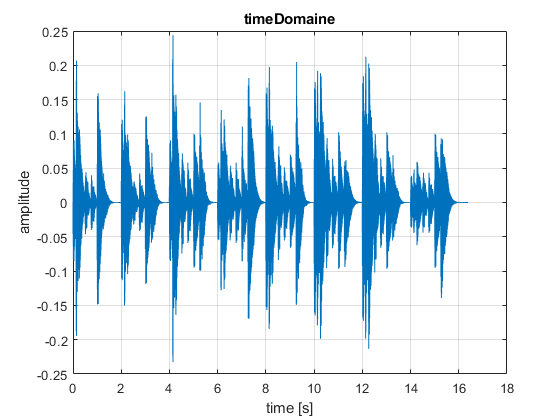

%time domaine signal
plot(time,signal)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("timeDomaine")

%stat info
maxValue = max(signal)

maxValue = 0.2438

minValue = min(signal)

minValue = -0.2328

meanValue = mean(signal)

meanValue = -5.1617e-05

stdValue = std(signal) %standart deviation

stdValue = 0.0323

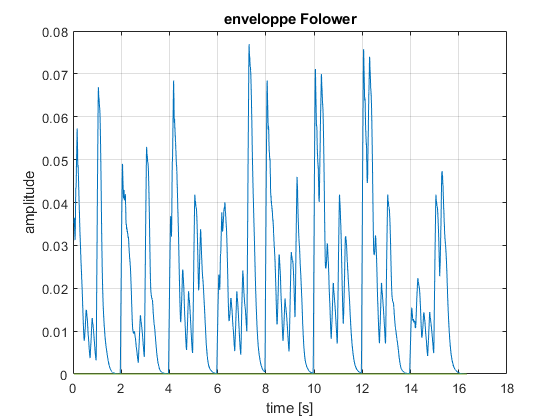

plot(newTime ,EnveloppeFolow)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("enveloppe Folower")

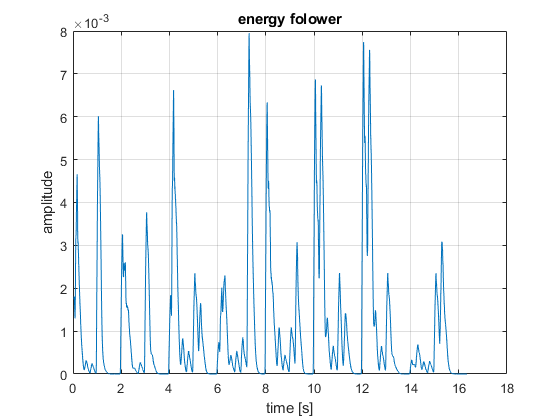



plot(newTime,LocalEnergieFolow)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("energy folower")

LocalEnergieFolow_maxValue = max(LocalEnergieFolow)

LocalEnergieFolow_maxValue = 0.0080

LocalEnergieFolow_minValue = min(LocalEnergieFolow)

LocalEnergieFolow_minValue = 3.7517e-10

LocalEnergieFolow_meanValue = mean(LocalEnergieFolow)

LocalEnergieFolow_meanValue = 0.0010

LocalEnergieFolow_stdValue = std(LocalEnergieFolow) %standart deviation

LocalEnergieFolow_stdValue = 0.0015

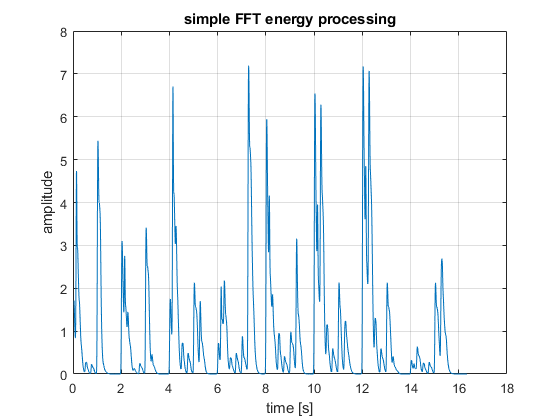

plot(newTime,FFT_SimpleEnergie)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("simple FFT energy processing")

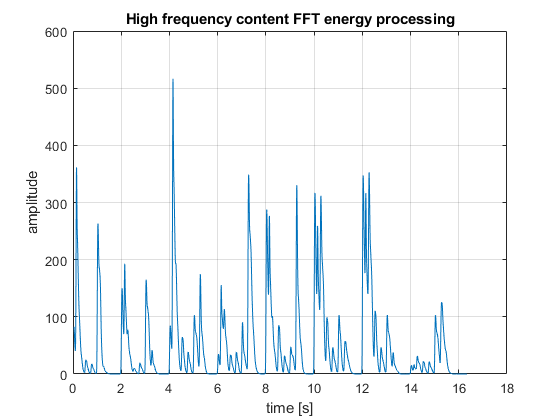

plot(newTime,FFT_HFC)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("High frequency content FFT energy processing")

%stat info
FFT_HFC_maxValue = max(FFT_HFC)

FFT_HFC_maxValue = 516.5698

FFT_HFC_minValue = min(FFT_HFC)

FFT_HFC_minValue = 3.2618e-05

FFT_HFC_meanValue = mean(FFT_HFC)

FFT_HFC_meanValue = 48.5155

FFT_HFC_stdValue = std(FFT_HFC) %standart deviation

FFT_HFC_stdValue = 73.7572

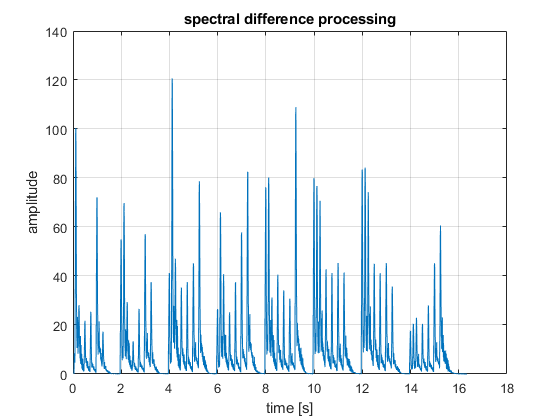

plot(newTime,FFT_spectralDiff)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("spectral difference processing")

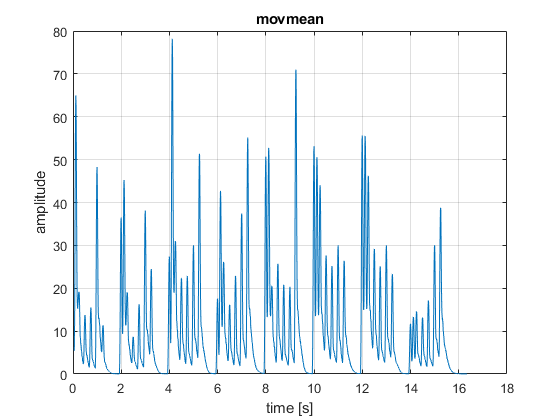


M = movmean(FFT_spectralDiff,15);
plot(newTime,M)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("movmean")

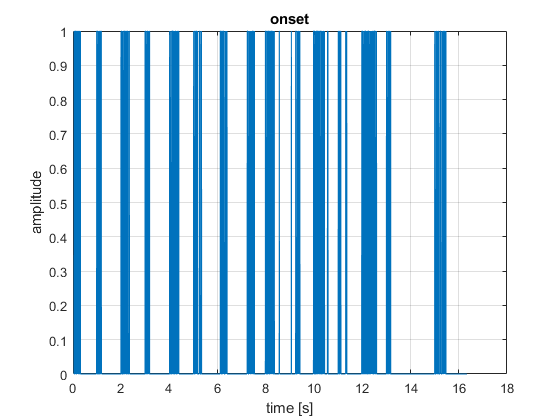

onset = zeros(size(M));
onsetTime = zeros(size(M));

for indexTime = 1 : size(M)
    if(FFT_spectralDiff(indexTime) >= M(indexTime))
        if(LocalEnergieFolow(indexTime)> LocalEnergieFolow_meanValue)
            onset(indexTime) = 1;
        end
    else
        onset(indexTime) = 0;
    end
    if(onset(indexTime) == 1 && onset(indexTime-1) == 0)
        onsetTime(indexTime) =1;
    
    end
    
end
plot(newTime,onset)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("onset")

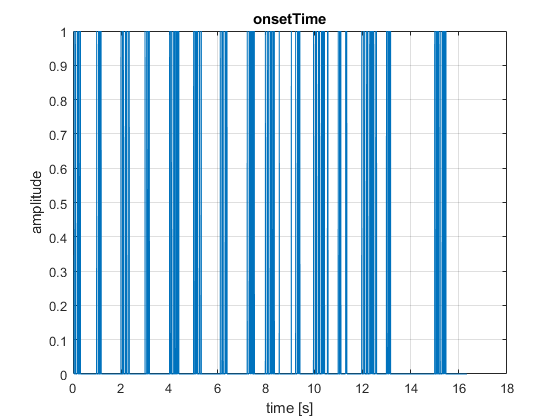

plot(newTime,onsetTime)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("onsetTime")

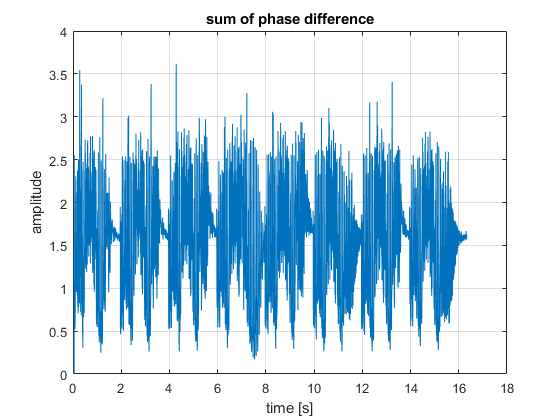

plot(newTime,sumDeltaPhi)
grid on
xlabel("time [s]")
ylabel("amplitude")
title("sum of phase difference")

test = mirevents( 'AudioTest\130BPM_PIANO_multiNote.wav','Detect')

Error using audioinfo (line 51)
The filename specified was not found in the MATLAB path.

Error in mirread2015>audioreader (line 94)
    i = audioinfo(file);

Error in 

mirgetdata(test)
